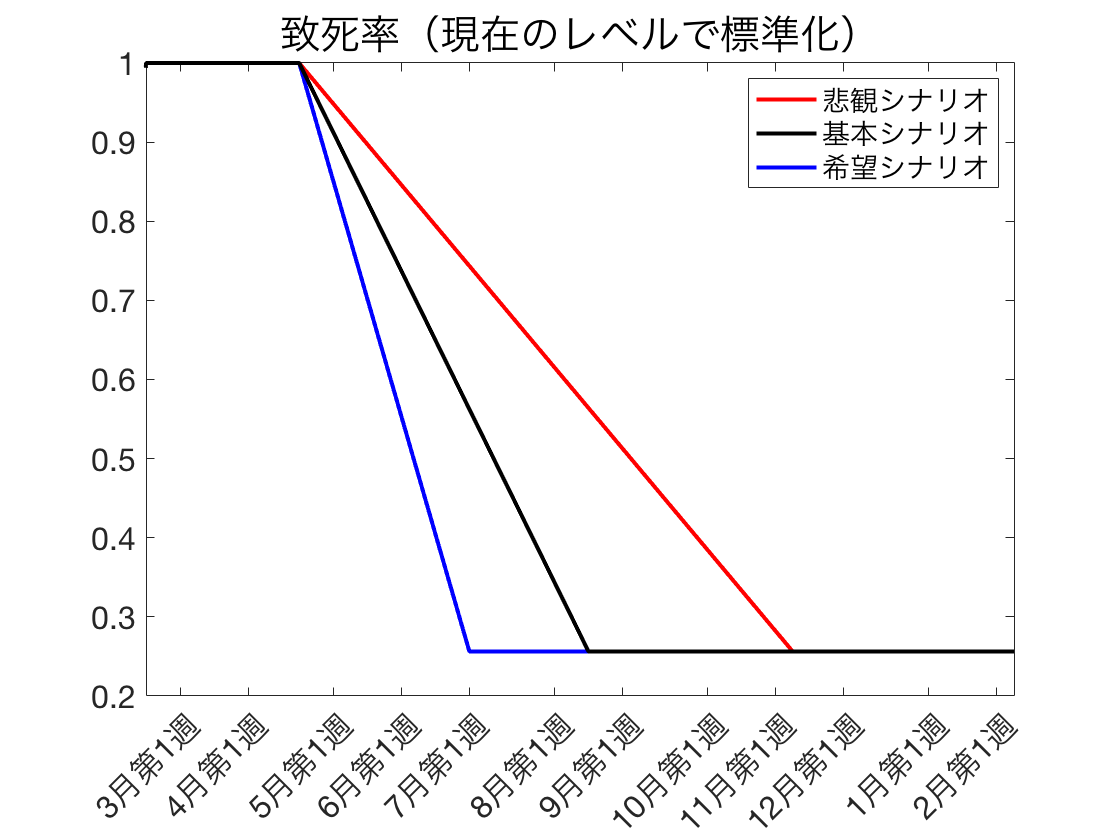

% This m-file executes simulation and generates figures for the main
% analysis of "Covid-19 and Output in Japan" by Daisuke Fujii and Taisuke
% Nakata

clear variables
close all
home = '/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Codes/';
%home = '/Users/Daisuke/Desktop/Dropbox/Research/fujii_nakata/Website/Covid19OutputJapan.github.io/archives/20210202/';
cd(home);



%====================== Program parameter values ======================%
figure_save = 0;    % 0 = figures won't be saved, 1 = they will be saved
mat_save = 0;    % 0 = figures won't be saved, 1 = they will be saved
% in the "Figure" folder
fs = 16;            % common font size for many figures
xlim_tradeoff = [1,2.5];
iDrawUB=0;          % 0 = create quasi-UB without simulations, 1 = create UB with simulations
Nsim=30000;         % if iDrawUB=1, this is the number of draws you use.
%======================================================================%

%====================== Model parameter values ======================%
pref = 'Japan';        % prefecture to be analyzed
POP0 = 125710000;      % initial population
gamma = 7/5;          % recovery rate from Covid
k = 2;                 % exponent of (1-h*alpha)
hconstant = 1;         % 0 = without intercept, 1 = with intercept for h regression
TargetAlpha = 0.5:0.1:3;      % values of alpha we simulate results
AlphaVals = [1.2,1.65,2.5];   % benchmark alpha we plot time-series figures
SimPeriod = 52;        % simulation period in weeks
medical_start_date = "Mar-18";
elderly_start_date = "Apr-01";
% VacStartDate = "Apr-01";         % time until the start of vaccination process
% VacPace = 0.8*(3000000/2); % number of vaccinated persons per week (steady pace)
% VacDuration = 12;       % time until vaccination pace reaches its steady pace
RetroPeriod = 17;      % retroactive periods used to estimate gamma and delta
wl = [1,2];            % Results as of these weeks ago
%====================================================================%


%--- Import data ---%
% Covid data are recorded at weekly frequencies (Mon-Sun)
% The first week start on January 20 (Mon), 2020
covid = importdata([home 'Covid_weekly.csv']);  % Import weekly Covid data
Data = covid.data(strcmp(covid.textdata(2:end,1),pref),:);
dateD = Data(:,1) + 21916;
N = Data(:,2);
dD = Data(:,3);
M = Data(:,4);
GDP = Data(:,5);
POP = Data(:,6);
Tdata= size(Data,1);    % Data period in weeks
POP0 = POP(1);          % initial population
ps = POP0/125710000;    % population share
xtick1 = 1:13:Tdata;
dateJP = string(datetime(dateD,'ConvertFrom','excel','Format','M月dd日'));
dateEN = string(datetime(dateD,'ConvertFrom','excel','Format','MMM-dd'));
Month = string(datetime(dateD,'ConvertFrom','excel','Format','MMM-yy'));
SimDate = dateD(end)+7:7:dateD(end)+7*SimPeriod;
SimDateEN = string(datetime(SimDate,'ConvertFrom','excel','Format','MMM-dd'));
%--- Create Month-Week labels ---%
dateP = dateD(end)+7:7:dateD(end)+7*(SimPeriod+1);
date = [dateD;dateP'];
MonthNumber = month(datetime(date,'ConvertFrom','excel'));
WeekNumber = zeros(length(MonthNumber),1);
WeekNumber(1:2) = [3;4];
for i = 3:length(WeekNumber)
    if MonthNumber(i)~=MonthNumber(i-1)
        WeekNumber(i) = 1;
    else
        WeekNumber(i) = WeekNumber(i-1) + 1;
    end
end
MonthWeekJP = strings([length(MonthNumber),1]);
MonthWeekEN = strings([length(MonthNumber),1]);
for i = 1:length(MonthNumber)
    MonthWeekJP(i) = [char(string(MonthNumber(i))) '月第' char(string((WeekNumber(i)))) '週'];
    MonthWeekEN(i) = [char(string(datetime(date(i),'ConvertFrom','excel','Format','MMM'))) '-' char(string((WeekNumber(i)))) 'w'];
end

M = 1+0.01*M;
TdataGDP = Tdata-sum(isnan(GDP));
RetroH = TdataGDP-4;
VacStart = find(SimDateEN == "Apr-01");
medical_start = find(SimDateEN == medical_start_date);
elderly_start = find(SimDateEN == elderly_start_date);
End2020 = find(dateEN == "Jan-07");

%--- Constructing the reference level of output ---%
potentialGDP = zeros(52*3,1);       % potential GDP for the next 3 years
potentialGDP(1) = (548182/(1.0122))*(1.0063^(1/12));
for i = 2:length(potentialGDP)
    if i <= 13
        potentialGDP(i) = potentialGDP(i-1)*(1.0063^(1/52));
    elseif i <= 52
        potentialGDP(i) = potentialGDP(i-1)*(1.0021^(1/52));
    elseif i <= 104
        potentialGDP(i) = potentialGDP(i-1)*(1.0024^(1/52));
    elseif i <= 156
        potentialGDP(i) = potentialGDP(i-1)*(1.0021^(1/52));
    end
end
% gapGDP = zeros(length(potentialGDP),1);
% gapGDP(1) = 0.0166;
% for i = 2:length(gapGDP)
%     gapGDP(i) = gapGDP(i-1)*(0.975^(12/52));
% end
referenceGDP = potentialGDP.*(1+0.0166);
referenceGDP(1:2) = [];


%--- Impute alpha (regress alpha on M)---%
Malt=M;
Malt(50)=0.5*(Malt(49)+Malt(51));
alpha = (1 - GDP(1:TdataGDP)./referenceGDP(1:TdataGDP));   % output loss in percentage
X = M(TdataGDP-17:TdataGDP);
Y = alpha(TdataGDP-17:TdataGDP);
XC = [ones(length(X),1), X];
s = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
reg = XC*s;
r = Y - reg;
SSE = sum(r.^2);
eps_p = zeros(Tdata-TdataGDP,1);
eps_p(1) = r(end);
for i = 1:Tdata-TdataGDP-1
    eps_p(i+1) = 1*eps_p(i);
end
alpha_pred = s(1)+s(2)*Malt(TdataGDP+1:Tdata)+eps_p;

alpha = [alpha;alpha_pred];

%--- Regress mobility on alpha to estimate the elasticity h ---%
Y = M(4:TdataGDP);
X = alpha(4:TdataGDP);
if hconstant == 0
    Y = Y - 1;
    h_all = (X'*X)\X'*Y;              % OLS estimate of h
    reg = X*h_all;
    r = Y - reg;                % r is the residuals, which is the observed minus fitted values
    SSE = sum(r.^2);            % SSE is the sum of squared errors
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_all_se=sqrt(MSE/sum(X.^2));   % standard error of h
elseif hconstant == 1
    XC = [ones(length(X),1), X];
    h_all = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
    reg = XC*h_all;
    r = Y - reg;
    SSE = sum(r.^2);
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_all_se = zeros(2,1);
    h_all_se(1)=sqrt(MSE/sum(XC(:,1).^2));   % standard error of h
    h_all_se(2)=sqrt(MSE/sum(XC(:,2).^2));
end

Y = M(TdataGDP-RetroH:TdataGDP);
X = alpha(TdataGDP-RetroH:TdataGDP);
if hconstant == 0
    Y = Y - 1;
    h = (X'*X)\X'*Y;              % OLS estimate of h
    reg = X*h;
    r = Y - reg;                % r is the residuals, which is the observed minus fitted values
    SSE = sum(r.^2);            % SSE is the sum of squared errors
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_se=sqrt(MSE/sum(X.^2));   % standard error of h
elseif hconstant == 1
    XC = [ones(length(X),1), X];
    h = (XC'*XC)\XC'*Y;         % OLS estimate of h with constant
    reg = XC*h;
    r = Y - reg;
    SSE = sum(r.^2);
    MSE=SSE/(length(Y)-1);      % mean squared error
    h_se = zeros(2,1);
    h_se(1)=sqrt(MSE/sum(XC(:,1).^2));   % standard error of h
    h_se(2)=sqrt(MSE/sum(XC(:,2).^2));
end



%--- Compute the history of S, I, R, D in the data period ---%
S = zeros(Tdata+1,1);
I = zeros(Tdata+1,1);
R = zeros(Tdata+1,1);
D = zeros(Tdata+1,1);
S(1)=POP0;
for i = 1:Tdata
    S(i+1)=S(i)-N(i);
    I(i+1)=I(i)+N(i)-gamma*I(i)-dD(i);
    R(i+1)=R(i)+gamma*I(i);
    D(i+1)=D(i)+dD(i);
    if i > TdataGDP
        GDP(i) = referenceGDP(i)*(1-alpha(i));
    end
end

%--- Compute the history of time-varying parameters ---%

delta = (D(2:Tdata+1)-D(1:Tdata))./I(1:Tdata);                              % death rate
beta_tilde = -POP0*((S(2:Tdata+1)-S(1:Tdata))./(S(1:Tdata).*I(1:Tdata)));   % overall infection rate
ERN = (S(1:end-1)/POP0).*beta_tilde./(gamma+delta);                                        % effective reproduction number
if hconstant == 0
    beta = beta_tilde./(1+h_all*alpha).^k;                                      % raw infection rate
elseif hconstant == 1
    %     beta = beta_tilde./(h(1)+h(2)*alpha).^k;
    beta = beta_tilde./(1+(h_all(2)/h_all(1))*alpha).^k;
end
AverageAlpha2020 = 100*mean([alpha(1);alpha(2);alpha(1:End2020)]);



%%%%%%%%%%%%%%%%% Projection starts here %%%%%%%%%%%%%%%%%

%--- Construct time series of parameters ---%
gammaT = gamma*ones(SimPeriod,1);
beta_sample = beta(end-RetroPeriod+1:end);
beta_average = mean(beta_sample);
betaT = mean(beta_sample)*ones(SimPeriod,1);
delta_sample = delta(end-RetroPeriod+1:end);
delta_average = mean(delta_sample);

pace = 3500000;
medical = 3700000*0.8;
elderly = 36000000*0.8;
ordinary = (125710000-36000000-3700000)*0.8;
elderly_total = 36000000;
vp = [2000000,3500000,6000000];
delta_mat = zeros(SimPeriod,3);
VT_mat = zeros(SimPeriod,6,3);
for i = 1:length(vp)
[V,delta_mat(:,i),VT_mat(:,:,i),real_pace] = vaccine_path(vp(i),SimPeriod,medical,elderly,ordinary,medical_start,elderly_start,4,0.9,delta_average,elderly_total);
end

delta_mat = delta_mat./delta_average;


figure(1)
plot([zeros(Tdata,1);delta_mat(:,1)],'-r','LineWidth',2,'DisplayName','悲観シナリオ')
hold on
plot([zeros(Tdata,1);delta_mat(:,2)],'-k','LineWidth',2,'DisplayName','基本シナリオ')
hold on
plot([zeros(Tdata,1);delta_mat(:,3)],'-b','LineWidth',2,'DisplayName','希望シナリオ')
hold on
plot([zeros(Tdata,1);delta_mat(:,2)],'-k','LineWidth',2,'HandleVisibility','off')
ax = gca;
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;
%ax.YAxis.Exponent = 0;
%ytickformat('%,6.0f')
xticks(find(WeekNumber==1))
title('致死率（現在のレベルで標準化）','FontSize',20,'FontWeight','normal')
xticklabels(MonthWeekJP(WeekNumber==1))

lgd = legend;
lgd.NumColumns = 1;
lgd.FontSize = 14;
%lgd.Location = 'north';
xtickangle(45)
xlim([Tdata+1 Tdata+SimPeriod])
%ylim([0, 0.025])
saveas(figure(1),[home 'Figures/delta_path.png']);